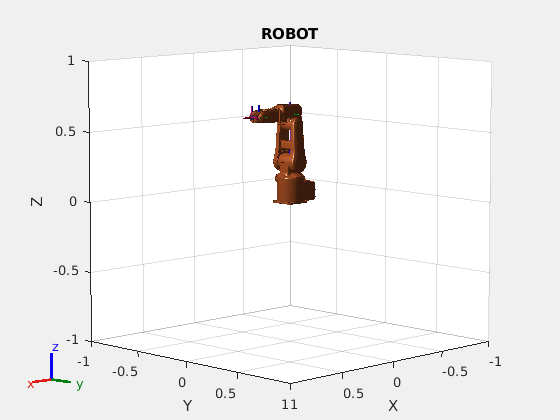

robo = loadrobot('abbIrb120');
ax = show(robo);
title(ax,'ROBOT');
hold('on');

pts = readtable('DataScience/project/archive/angles.csv');
pts

pts = 77419×9 table
       q1          q2          q3            q4            q5         q6           x             y            z    
    ________    ________    _________    ___________    _________    _____    ___________    _________    _________

       1.122      1.7285      0.26157       0.064988     0.078599        0       0.074851      0.15626     -0.12001
      2.1596      1.9199     -0.29175          1.682       1.4341        0       -0.23314      0.22145     -0.11811
     -1.3317    -0.95923      0.92973        0.29313      -1.4619        0    -7.0047e-05    -0.087032      0.59262
      2.0646      0.8633    -0.040496     -0.0019533       -1.053        0       -0.25227    


x = pts(:,7);
y = pts(:,8);
z = pts(:,9);

x_d = table2array(x);
y_d = table2array(y);
z_d = table2array(z);

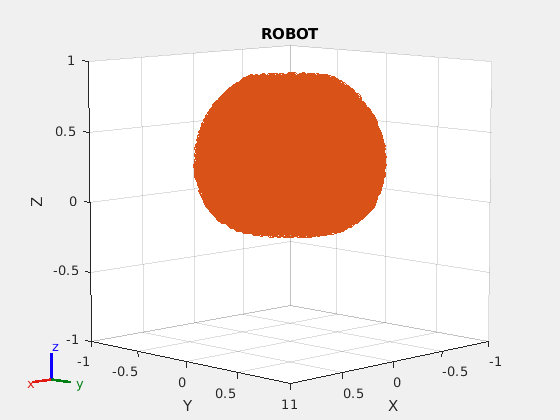

scatter3(ax,x_d,y_d,z_d);
hold('off');

robo.BodyNames

ans = 1×8 cell array
    {'base'}    {'link_1'}    {'link_2'}    {'link_3'}    {'link_4'}    {'link_5'}    {'link_6'}    {'tool0'}


i = 1201;
pos = [x_d(i) y_d(i) z_d(i)];
posvec = trvec2tform(pos);
disp(posvec)

    1.0000         0         0    0.0689
         0    1.0000         0    0.2482
         0         0    1.0000   -0.0942
         0         0         0    1.0000



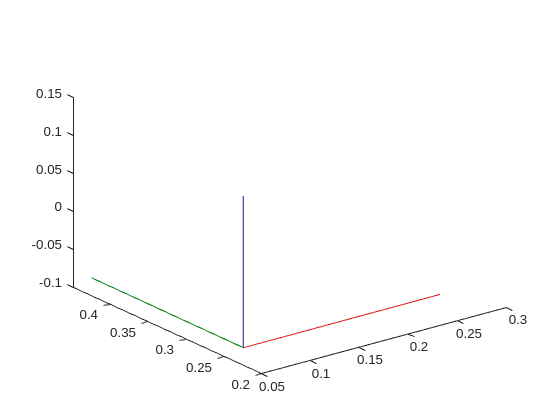

plotTransforms(pos,eul2quat([0 0 0]),FrameSize=0.2);


ik = inverseKinematics("RigidBodyTree",robo);

Unrecognized function or variable 'robo'.

weights = [0 0 0 1 1 1];
initialguess = homeConfiguration(robo);

[configSoln,solnInfo] = ik("link_6",posvec,weights,initialguess);

disp(configSoln);

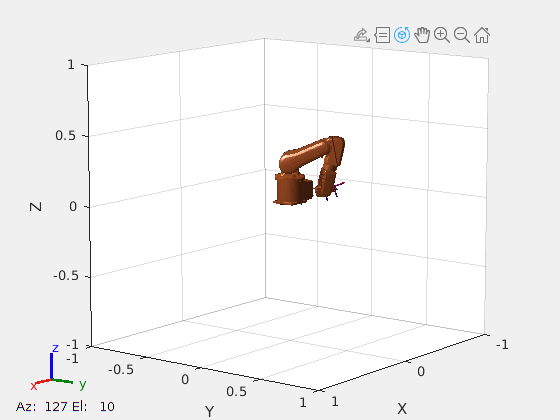

show(robo,configSoln);
hold('off');

pose = getTransform(robo,configSoln,"link_6");
disp(pose);

   -0.7287    0.6243   -0.2815   -0.1803
    0.6156    0.7773    0.1301    0.2512
    0.3000   -0.0784   -0.9507    0.1165
         0         0         0    1.0000



**RANDOM JOINT CONFIGURATION FROM GIVEN DATASET** 

config = pts(i,1:6);
config = table2array(config);
disp('COnfig: ')

COnfig: 


disp(config);

    2.1244    1.1311    0.6711    2.7925    2.0944         0




home_config = homeConfiguration(robo)

home_config = 1×6 struct array with fields:
    JointName
    JointPosition


for i = 1:6
    home_config(i).JointPosition = config(i);
end
newpose = getTransform(robo,home_config,"link_6");
disp(newpose);

   -0.7287    0.6243   -0.2815   -0.1803
    0.6156    0.7772    0.1301    0.2512
    0.3000   -0.0784   -0.9507    0.1165
         0         0         0    1.0000



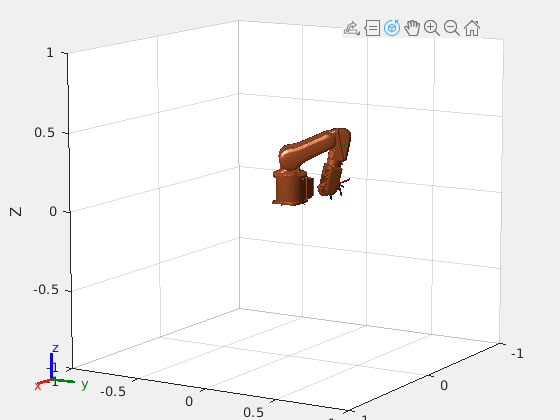

ans =   Axes (Primary) with properties:

             XLim: [-1 1]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


show(robo,home_config) 